### Direct attenuation


$$D_c =J_c e^{-\beta_c^D {\left(v_D \right)}z}$$
 

clear
clc

#### Data preparation

% color checker at depth d = [1 5] m
load('mat data\Colorchecker01_Kd_linear_RGBValue_BLACK.mat')
% load('mat data\Colorchecker01_Kd_linear_RGBValue.mat')

% CHANGE dimension arrangement for further calculating 
linearR_Kd = permute(linearR_Kd, [4 2 3 1]);
linearG_Kd = permute(linearG_Kd, [4 2 3 1]);
linearB_Kd = permute(linearB_Kd, [4 2 3 1]);

% ocean IOP: attenuation(beta)
load("mat data\Ocean_IOP_Jerlov.mat","beta_Jerlov")
beta_Jerlov = beta_Jerlov(5:17,:);

% refletancy of 24 color checkers: 380:10:730nm
% sequence from left top to right bottom
load('mat data\reflectance.mat')
for i = 1:7
    reflectance_new(:,2*i-1,:) = reflectance(:,3+5*(i-1),:);
    if i ~= 7
        reflectance_new(:,2*i,:) = (reflectance(:,5+5*(i-1),:) +  reflectance(:,6+5*(i-1),:))/2;
    end
end

% Sc: 400:10:720 nm
load("mat data\Sc_database.mat")
for i = 1:7
    Sc_new(:,2*i-1,:) = Sc(:,1+5*(i-1),:);
    if i ~= 7
        Sc_new(:,2*i,:) = (Sc(:,3+5*(i-1),:) +  Sc(:,4+5*(i-1),:))/2;
    end
end
% Sc_new = mean(Sc_new,3);
Sc_R = Sc_new(1,:,20);
Sc_G = Sc_new(2,:,20);
Sc_B = Sc_new(3,:,20);

% Kd: 300:25:700 nm
load("mat data\Kd_database.mat"); % load Kd of Jerlov's
Kd_Jerlov = Kd_Jerlov(5:17,:);

%distance
for i = 1:10
    z(:,:,i) = repmat(i,size(beta_Jerlov));
end

% depth
d = [1 5];
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};

#### Background light source E(d, $\lambda$)

% background light (white D65)
% E0 
[x, E0] = illuminant('d65');
E0 = E0(101:25:401);
x = x(101:25:401);

for i = 1:numel(typename)
    for j = 1:numel(d)
        Kd = Kd_Jerlov(:,i);
        Ed_Jerlov(:,i,j) = E0.* exp(-Kd(:)*d(j));
    end

end

#### XYZ tristimulus value

[lambda_2, xFcn, yFcn, zFcn] = colorMatchFcn('cie_1931');
num = 400:25:700;
for i = 1:length(num)
    n(i,:) = find(round(lambda_2)==round(num(i)));
end

for j = 1:length(n)
    xFcn_new(j) = xFcn(n(j));
    yFcn_new(j) = yFcn(n(j));
    zFcn_new(j) = zFcn(n(j));
end
xyzFcn_new = [transpose(xFcn_new) transpose(yFcn_new) transpose(zFcn_new)];

#### Exponential Function understanding (Not yet be done)

x = 0:0.01:10

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


leg = 13×9 char array
    'a= 0.0282'
    'a=0.02182'
    'a=0.02181'
    'a=0.02206'
    'a=0.02849'
    'a=0.04805'
    'a= 0.0637'
    'a=0.08343'
    'a=0.22922'
    'a=0.29604'
    'a= 0.3349'
    'a=0.43478'
    'a=0.58269'


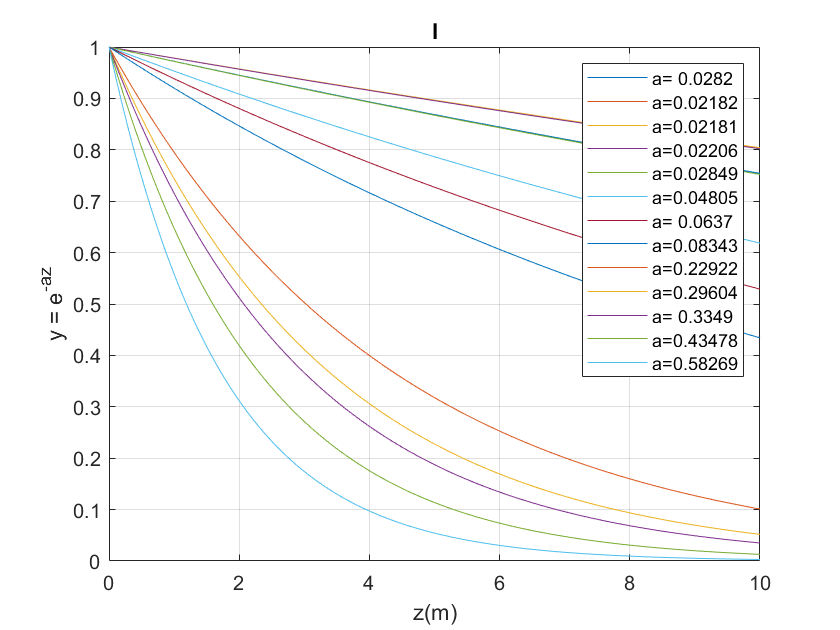

leg = 13×9 char array
    'a= 0.0387'
    'a=0.03005'
    'a=0.02841'
    'a=0.02696'
    'a=0.03281'
    'a=0.05082'
    'a=0.06574'
    'a=0.08525'
    'a=0.23083'
    'a=0.29756'
    'a=0.33634'
    'a=0.43714'
    'a=0.58398'


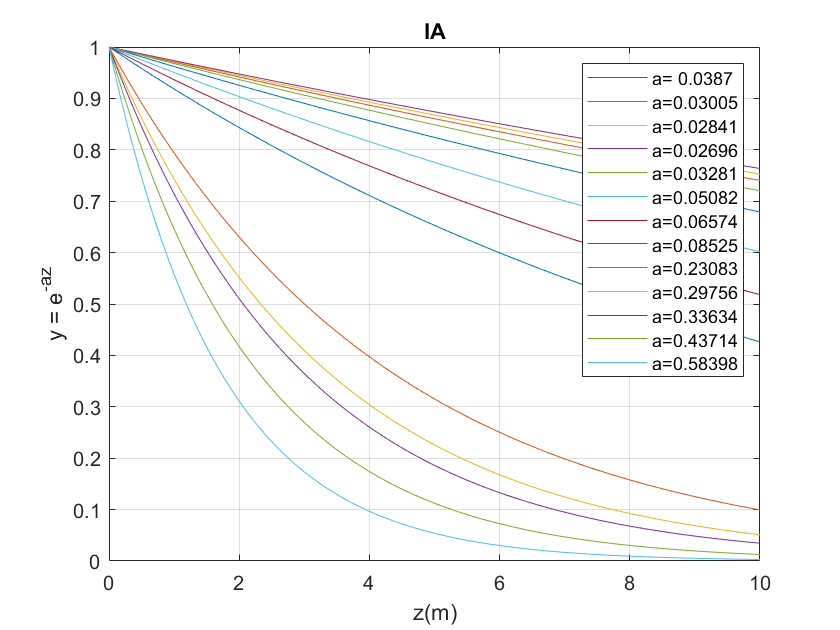

leg = 13×8 char array
    'a=0.1126'
    'a=0.0978'
    'a=0.0915'
    'a= 0.086'
    'a=0.0884'
    'a=0.1034'
    'a=0.1159'
    'a=0.1333'
    'a=0.2766'
    'a=0.3428'
    'a= 0.379'
    'a=0.4784'
    'a= 0.624'


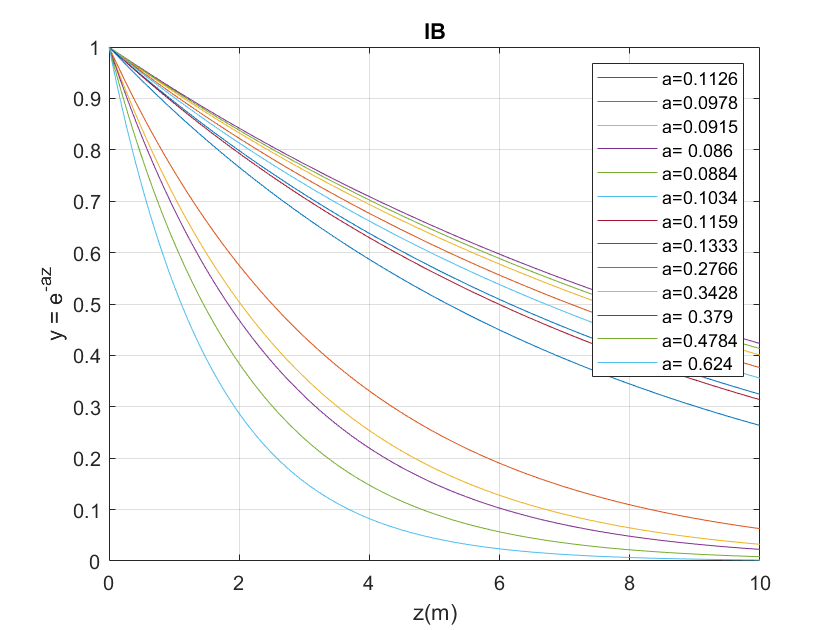

leg = 13×8 char array
    'a=0.6515'
    'a=0.5807'
    'a=0.5281'
    'a=0.4818'
    'a=0.4498'
    'a=0.4339'
    'a=0.4202'
    'a=0.4141'
    'a= 0.537'
    'a= 0.584'
    'a= 0.604'
    'a= 0.689'
    'a= 0.766'


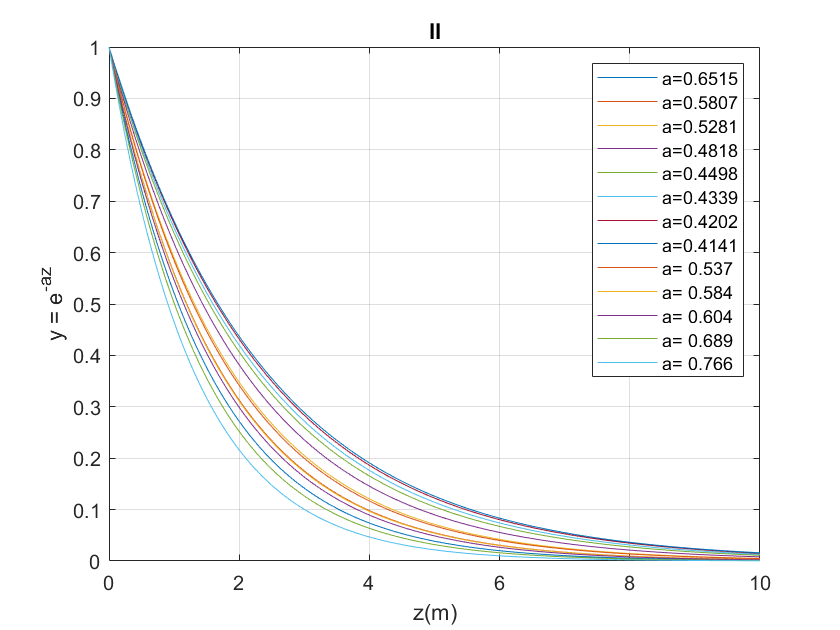

leg = 13×8 char array
    'a=1.7515'
    'a=1.5649'
    'a=1.4188'
    'a=1.2935'
    'a=1.1878'
    'a=1.1107'
    'a=1.0446'
    'a=0.9918'
    'a= 1.074'
    'a= 1.085'
    'a= 1.073'
    'a= 1.131'
    'a= 1.233'


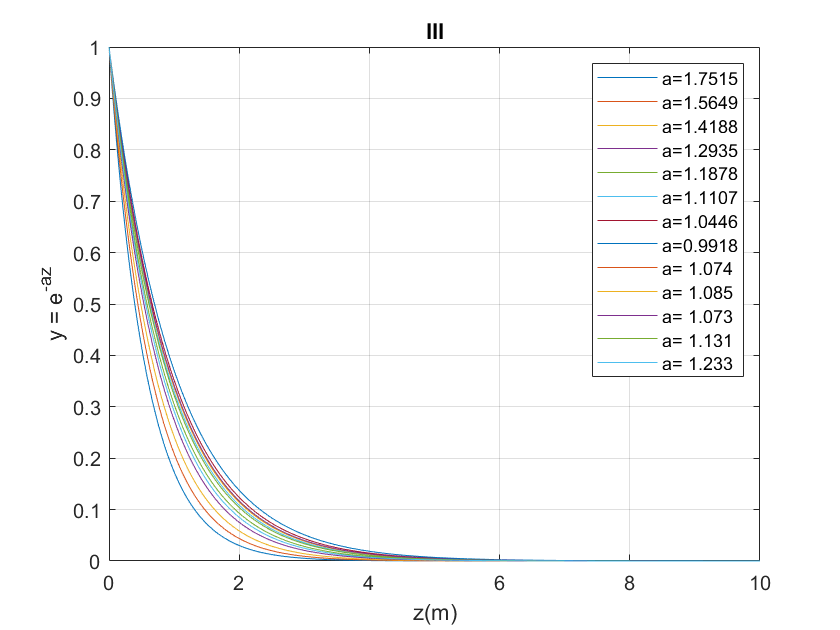

leg = 13×7 char array
    'a=0.857'
    'a=0.714'
    'a=0.619'
    'a=0.546'
    'a=0.493'
    'a=0.463'
    'a=0.441'
    'a= 0.43'
    'a= 0.55'
    'a=0.597'
    'a=0.618'
    'a=0.712'
    'a=0.828'


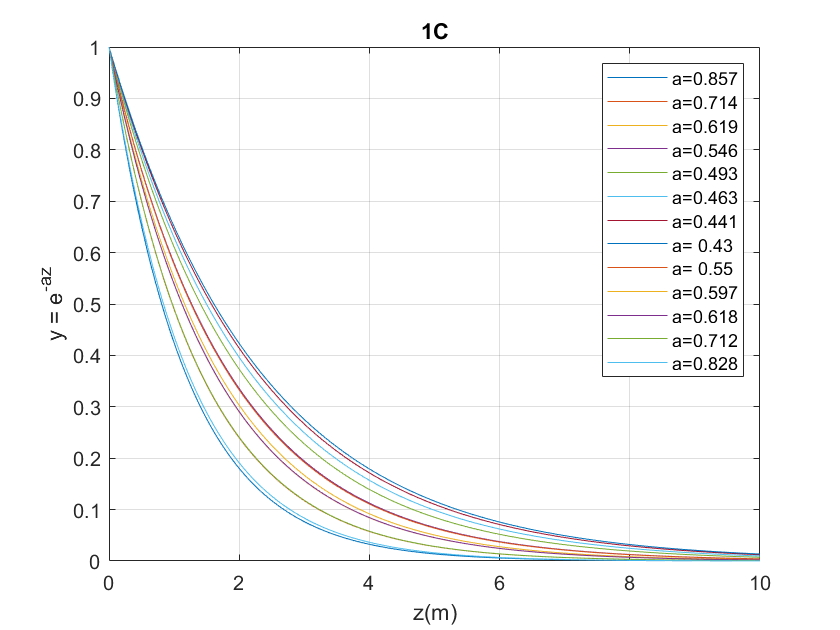

jerlov = {'I','IA', 'IB', 'II', 'III', '1C'};
for i = 1:6
    figure
    a = beta_Jerlov(:,i);
    plot(x, exp(-a.*x))

    grid on
    xlabel('z(m)')
    ylabel('y = e^{-az}')
    title(jerlov{i})
    leg = strcat(repmat('a=',[13,1]),num2str(a))
    legend(leg)
    set(gcf,'Visible','on')
end

#### Sc * p * E

sequence = [19 13 7 1 20 14 8 2 21 15 9 3 22 16 10 4 23 17 11 5 24 18 12 6]

sequence =     19    13     7     1    20    14     8     2    21    15     9     3    22    16    10     4    23    17    11     5    24    18    12     6


for j = [1 10]
    dz = j;
    for i = 2
        for k = 10%color
            dz=0.0001
            %Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i)
%             exp(-beta_Jerlov.*(z(:,:,j)+dz))
            sum(100.*Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz)))
            far = log(sum(Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))));
            
%             exp(-beta_Jerlov.*z(:,:,j))
            sum(100.*Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))
            near = log(sum(Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j))));
            
            substra = near - far;

            result = substra / dz;
        end
    end
end

dz = 1.0000e-04

ans =   955.6532  947.6974  872.9848  583.2685  261.7475  436.9925  171.8370   17.8140


ans =   955.6749  947.7191  873.0090  583.3003  261.7759  437.0169  171.8569   17.8168


result =     0.2265    0.2289    0.2763    0.5452    1.0850    0.5593    1.1595    1.5831


dz = 1.0000e-04

ans =   206.8040  198.2488  114.0501    5.1926    0.0170    3.4260    0.0056    0.0001


ans =   206.8064  198.2511  114.0522    5.1929    0.0170    3.4262    0.0056    0.0001


result =     0.1140    0.1191    0.1761    0.5019    1.0628    0.5164    1.1415    1.3606


#### Direct attenuation coefficient


$$\beta_c^D =\ln {\left[\frac{\int_{\lambda_1 }^{\lambda_2 } S_c \left(\lambda \right)\rho \left(\lambda \right)E\left(d,\lambda \right)e^{-\beta \left(\lambda \right)z} d\lambda }{\int_{\lambda_1 }^{\lambda_2 } S_c \left(\lambda \right)\rho \left(\lambda \right)E\left(d,\lambda \right)e^{-\beta \left(\lambda \right)\left(z+\Delta z\right)} d\lambda }\right]}/\Delta z$$


% sequence of spectral refletancy: https://zhuanlan.zhihu.com/p/99108732
sequence = [19 13 7 1 20 14 8 2 21 15 9 3 22 16 10 4 23 17 11 5 24 18 12 6];

%METHOD 1 :Sc
for j = 1:10
    dz = j;
    for i = 1:numel(d)
        for k = 1:24 %color
            att_dir_R(j,:,i,k) = log(sum(Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(Sc_R' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
            att_dir_G(j,:,i,k) = log(sum(Sc_G' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(Sc_G' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
            att_dir_B(j,:,i,k) = log(sum(Sc_B' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(Sc_B' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
        end
    end
end

% %METHOD 2 :CIE XYZ
% for j = 1:10
%     for i = 1:numel(d)
%         for k = 1:24 %color
%             att_dir_R_cie(j,:,i,k) = log(sum(xFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(xFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
%             att_dir_G_cie(j,:,i,k) = log(sum(yFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(yFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
%             att_dir_B_cie(j,:,i,k) = log(sum(zFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*z(:,:,j)))./ sum(zFcn_new' .* reflectance_new(sequence(k),:)' .* Ed_Jerlov(:,:,i) .* exp(-beta_Jerlov.*(z(:,:,j)+dz))))./dz;
%         end
%     end
% end

#### save direct attenuation coefficient value to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker03_Attenuation_direct_BLACK.mat"),"att_dir_R","att_dir_G","att_dir_B")

#### Direct attenuation image


$$D_c =J_c e^{-\beta_c^D {\left(v_D \right)}z}$$
 

z = 1:10;
Dc_R_linear = linearR_Kd .* exp(-att_dir_R .* z');
Dc_G_linear = linearG_Kd .* exp(-att_dir_G .* z');
Dc_B_linear = linearB_Kd .* exp(-att_dir_B .* z');

save Dc image to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker03_Dc_linear_RGBValue_BLACK.mat"),"Dc_R_linear","Dc_G_linear","Dc_B_linear")

#### Direct attenuation image from linear sRGB to RGB

Dc_R = lin2rgb(Dc_R_linear);
Dc_G = lin2rgb(Dc_G_linear);
Dc_B = lin2rgb(Dc_B_linear);

PLOT

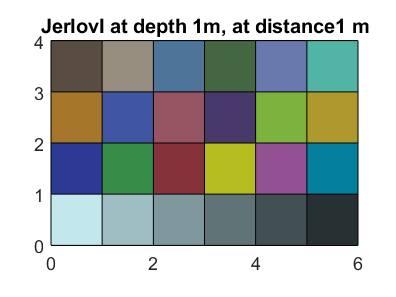

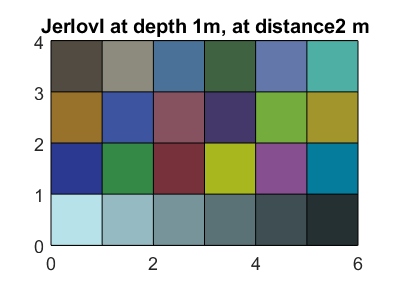

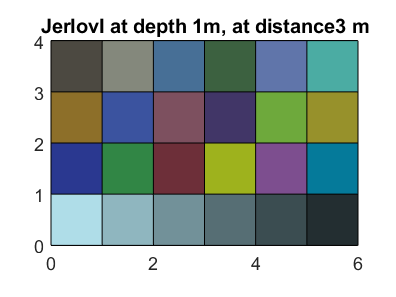

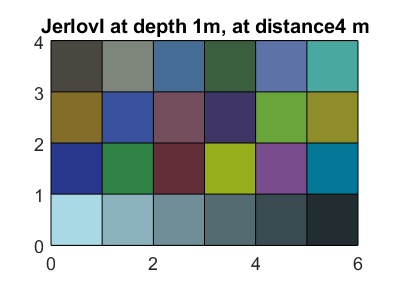

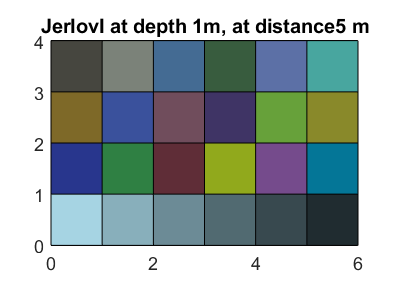

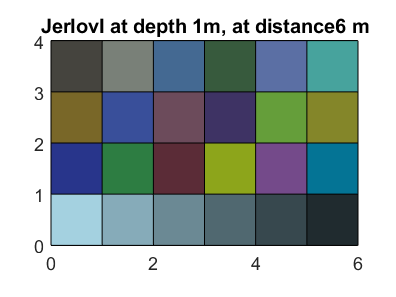

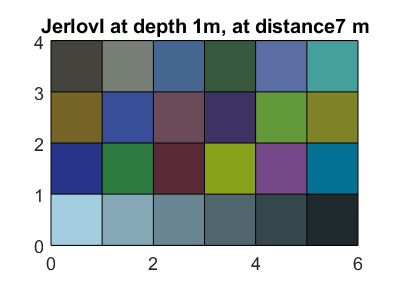

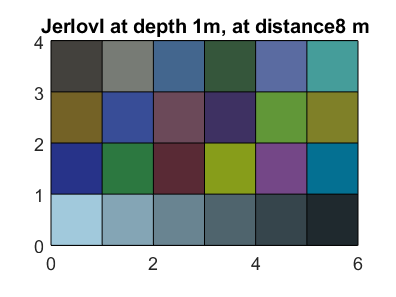

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\資料整理\Dc_image\';
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};
d = [1 5];
z = [1:10];
for i = 1:numel(typename) % jerlov 8 types
    for j = 1:numel(d) %水深 2 depth
        for k = 1:10 %物距
        plotcolorpatch(Dc_R(k,i,j,:),Dc_G(k,i,j,:),Dc_B(k,i,j,:));
        title(strcat(typename{i}," at depth ",num2str(d(j)),'m, at distance ',num2str(z(k)),' m'))
%         set(gcf,"Visible","on")
        saveas(gcf,strcat(fpath,'Dc_',typename{i},"_depth",num2str(d(j)),'m_distance',num2str(z(k)),'m'),'bmp')
        end
    end
end

function plotcolorpatch(R,G,B)
Nr_R = reshape(R, 4, 6);
Nr_G = reshape(G, 4, 6);
Nr_B = reshape(B, 4, 6);
%%
x = 0 : 6;
y = 0 : 4;
%% 網格xy首末
x1 = [x(1) x(end)]';
y1 = [y(1) y(end)]';
%% 網格所有線的xData
x2 = repmat(x1, 1, length(y)-2);
x3 = repmat(x(2):x(end-1), 2, 1);
xData = [x2 x3];
%% 網格所有線的yData
y2 = repmat(y1, 1, length(x)-2);
y3 = repmat(y(2):y(end-1), 2, 1);
yData = [y3 y2];
%% 繪製網格
figure
h = line(xData, yData);
box on;
set(h, 'Color', 'k');
%% 填色至各網格
for i = 1:4
    for j = 1:6
        xx = [0 1 1 0] + j - 1;
        yy = [0 0 1 1] + i - 1;
        patch('xData', xx, 'yData', yy, 'FaceColor', [Nr_R(i,j) Nr_G(i,j) Nr_B(i,j)]);
    end
end
axis equal
xlim(x1)
ylim(y1)
end
